# Práctica 3. Sistemas dinámicos continuos

## Identificación del alumno

Nombre: Ana 

Apellidos: Robledano Abasolo

Grupo:  B

DNI:  51504162D                               Problemas nº:   2    y  nº:   5

## Instrucciones

- Tiene el tiempo de clase para realizar la práctica

- Rellena tu identificación. No rellenar correctamente la identificación restará 1.0 puntos en la calificación final.

- Identifica los problemas a resolver. No borres el resultado.

- Rellena los números de los dos problemas en el lugar adecuado de tu identificación.

- Nombra el archivo de la forma indicada. Nombrarlo mal resta 0.5 puntos a la calificación final.

- Lee la rúbrica para conocer cómo se va a corregir la práctica.

- Cuando tengas la seguridad de saber lo que se te va a pedir y cómo se te va a calificar, continúa en el punto siguiente.

- Resuelve los dos problemas. No cometas faltas de ortografía. Las confusiones debidas al uso del teclado no se considerarán como tales.

- Vuelve a leer todas las instrucciones. Comprueba que todo es correcto.

- Repasa la práctica. Corrige lo que sea necesario. Incluyendo faltas de ortografía o de escritura.

- Sube el archivo al lugar habilitado para ello en el Canvas.

## Identificar los problemas a resolver

NO MODIFIQUE NADA DEL SIGUIENTE CÓDIGO

**Corra el programa siguiente e introduce tu DNI ****cuando te lo pida****:**

clear, clc
DNIt = inputdlg('INTRODUCIR EL DNI SIN LETRA NI PUNTOS');
if isempty(cell2mat(DNIt))
    errordlg('No puede dejar el DNI vacío', 'Error en la entrada')
    return
end
rng(str2num(cell2mat(DNIt)))
prob1 = ceil(5*rand);
prob2 = ceil(5*rand);

if prob1 == prob2
    while prob2 == prob1
        prob2 = ceil(5*rand);
    end
end

fprintf(1,'DNI = %s \n', cell2mat(DNIt))

DNI = 51504162 


fprintf(1,'Tiene que resolver los problemas: \n') 

Tiene que resolver los problemas: 


fprintf(1,'     Problema %1.0f  \n', prob1)

     Problema 2  


fprintf(1,'     Problema %1.0f  \n', prob2)

     Problema 5  


Instrucciones

## Entrega

Nombra el archivo como: **Apellido1Apellido2Nombre.zip** que contenga este fichero (con su nombre) y todos aquellos ficheros auxiliares que necesita para completar la práctica, incluidos los modelos de Simulink. Súbelo al enlace de la tarea. Nombrar mal el archivo restará 0.5 puntos en la calificación final.

Instrucciones

## Rúbrica

- Cada problema vale 4 puntos. Para ello, tiene que estar perfectamente resuelto, con explicaciones claras, sin líneas de código superfluas; bien explicado. Los textos con los resultados se deben mostrar por las funciones que tiene MATLAB para ello. Las figuras tienen que ser profesionales.

- 1 punto adicional por la limpieza, el orden y la claridad de las exposiciones y figuras.

## Problema 1				

Se sabe que la tasa de crecimiento de una determinada población de virus es directamente proporcional al número de virus existentes. Se realiza un cultivo en laboratorio, introduciendo 2.5 millones de virus en un recipiente. Se observa que la población se duplica cada 3 horas. Calcular la población existente al cabo de 11 horas. 

a) resolver el problema analíticamente.

b) construir el modelo en Simulink y verificar el resultado.		

### Solución		

## Problema 2

La población en el continente asiático en el año 2000 era de aproximadamente 4830 millones de personas y, en aquel momento, crecía a un ritmo de un 1.73% por año. Suponiendo que el crecimiento de la población se rigiera por el modelo exponencial, calcular el valor estimado de la población en dicho continente en el año 2025. 

a) resolver el problema analíticamente.

b) construir el modelo en Simulink y verificar el resultado.	

### Solución		

#### a) Resolver el problema analíticamente.

Modelo de crecimiento exponencial de la población del continente asiátocp.


$$\begin{array}{l}
\frac{\mathrm{dP}}{\mathrm{dt}}=r\cdot P\\
P\left(t\right)=\mathrm{población}\;\mathrm{en}\;\mathrm{un}\;\mathrm{tiempo}\;t\\
r=\mathrm{tasa}\;\mathrm{de}\;\mathrm{crecimiento}\;\\
\mathrm{con}\;P\left(t_o \right)=P_o \;
\end{array}$$


**Limpieza del entorno de trabajo**

clear     % limpieza del espacio de trabajo
clc       % limpieza de línea de comando
close all % cerrar todas las figuras

**Sustitución de datos del enunciado**

t0 = 2000; % Año del tiempo inicial
P0 = 4830; % Población en el tiempo inicial (en millones)
r = 0.0172;% Tasa de crecimiento 1.72%

**Resolución de la EDO**

Cálculo de la solución de la ecuación diferencial ordinaria con MATLAB:

syms P(t)
edo = diff(P, t, 1) == r*P;
cond = [P(t0)==P0];

P(t) = dsolve(edo, cond)

$$P(t) = 4830\,{\mathrm{e}}^{\frac{43\,t}{2500}}\,{\mathrm{e}}^{-\frac{172}{5}}$$

#### **Cálculo de la población en el 2025**

Sustitución del tiempo en la solución:

Pa_2025 = double(P(2025))

Pa_2025 = 7.4250e+03

#### **Gráfica de la solución**

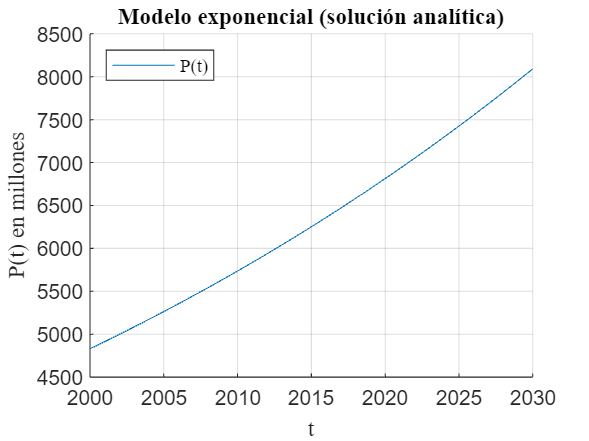

t_values = 2000:0.5:2030;
figure;
hold on; 
% Evaluar la solución en los valores de tiempo dados
P_values = subs(P, t, t_values);
    
% Graficar la solución
plot(t_values, P_values,'DisplayName','P(t)');
hold on 

% Detalles de la gráfica
xlabel('t','FontName','latex');
ylabel('P(t) en millones','FontName','latex');
title('Modelo exponencial (solución analítica)','FontName','latex');
grid on;
legend('show','Location','northwest','FontName','latex')
hold off;

#### b) Construir el modelo en Simulink y verificar el resultado.

#### **Configuración usuario **

Se muestran los ajustes elejidos por el usuario aplicables a cualquier modelo de simulación discreta. 

Configuración del solver

solver = struct();
solver.type = "Variable-Step";
solver.name = "ode45";
solver.start = 2000;
solver.stop = 2025;
solver.step = 1;

Nombre del modelo

model_name = "modelo5";

Condiciones iniciales y constantes del modelo:

r_values = 0.0173;
ic_values = [2000 4830];

sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output.

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout;
P1 = signals{1}.Values.Data;
P = signals{2}.Values.Data;
signal_time = signals{1}.Values.Time;

#### **Cálculo de la población en el 2025**

[m, ~] = size(P);
Pb_2025 = double(P(m)) % el último elemento de la simulación que finaliza en 2025

Pb_2025 = 7.4435e+03

#### Gráfica Simulink

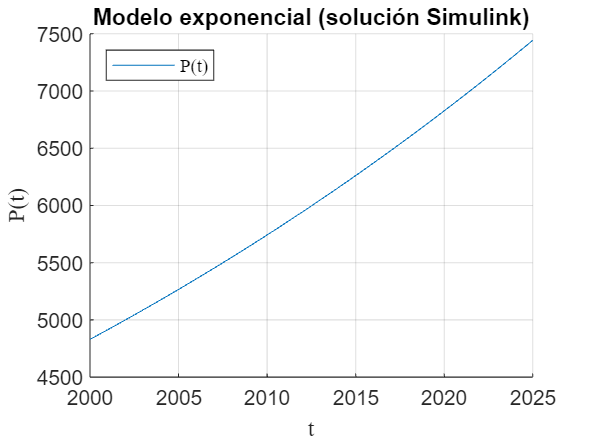

figure
hold on
% Gráfica de las señales
plot(signal_time, P,'DisplayName','P(t)')
grid on
% Detalles de la gráfica
title('Modelo exponencial (solución Simulink)');
xlabel('t','FontName','latex');
ylabel('P(t)','FontName','latex');
grid on;
legend('show','Location','northwest','FontName','latex')
hold off;

Juntamos las dos gráficas para ver si el resultado es el mismo (que a primera vista lo parece)

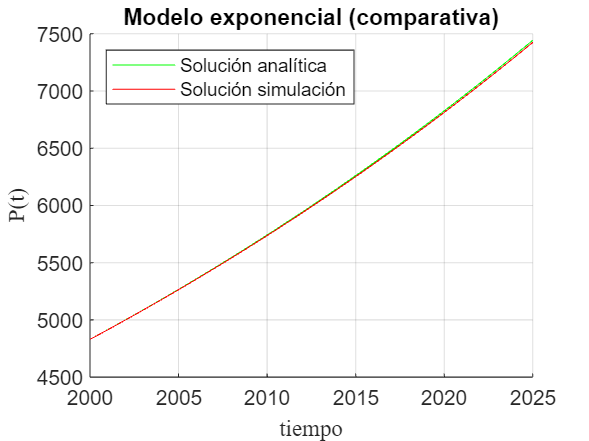

[m, n] = size(P1);
figure
xlim([2000, 2025])
hold on
plot(signal_time, P,'Color','g')
hold on
plot(t_values, P_values,'Color','r')
grid on
xlabel("tiempo","FontName","latex");
ylabel("P(t)","FontName","latex");
title('Modelo exponencial (comparativa)');
legend('Solución analítica','Solución simulación','Location','northwest');
hold off

Observamos que se superponen. Además la población para ambos en el 2025 es:

Pa_2025

Pa_2025 = 7.4250e+03

Pb_2025

Pb_2025 = 7.4435e+03

## Problema 3	

En un laboratorio se cultivan virus a razón de $v$ virus por día. La densidad de estos depende de la tasa de muerte $m$ de estos por día. Hacer una formulación razonable de este fenómeno, encontrar su solución general y  discutir dicha solución.

### Solución

## Problema 4

Considere la siguiente ecuación diferencial:

a) construya el modelo en Simulink.

b) trace las gráficas de $y$ con cada una de sus derivadas	

c) si el modelo es estable, estudiar analíticamente su estabilidad. En caso contrario, ¿depende la estabilidad de las condiciones iniciales?

### Solución

## Problema 5

En el problema del estudio del sistema de amortiguación de un coche, suponga que debemos añadir el efecto de la fricción de la rueda con el asfalto. Modifique las ecuaciones, construya el modelo con Simulink y pruebe el resultado con la entrada en escalón unitario.

### Solución	

#### Procedimiento

Definimos las variables del modelo de simulación de amortiguación de un coche.


$$\begin{array}{l}
x=\mathrm{posición}\;\mathrm{del}\;\mathrm{coche}\\
y=\mathrm{posición}\;\mathrm{del}\;\mathrm{resorte}\;\mathrm{en}\;\mathrm{el}\;\mathrm{extremo}\;\mathrm{del}\;\mathrm{muelle}\;\mathrm{de}\;\mathrm{las}\;\mathrm{ruedas}\;\mathrm{del}\;\mathrm{coche}\\
r=\mathrm{elevación}\;\mathrm{del}\;\mathrm{terreno}
\end{array}$$


El objetivo es modelar un sistema en donde el coche amortigue los baches del terreno a través de la suspensión del muelle. Para que el conductor, apenas note la irregularidad del terreno.

#### Ecuaciones del modelo

Las fuerzas que aplican al modelo son la fuerza elástica, la fuerza del cinética y la fuerza del resorte. 

(Recordamos que la derivada de la posición es la velocidad, y la derivada de la velocidad es la aceleración).


$$\begin{array}{l}
F_k =K_c \left(x-y\right)\\
F_c =C_c \left(x^{\prime } -y^{\prime } \right)\\
F_r =K_r \left(y-r\right)
\end{array}$$


La fuerza elástica es proporcional a la posición de *x* e *y*. Con *Kc* constante elástica.

La fuerza del coche es proporcional a la velocidad relativa entre *x* e *y*.

La fuerza del resorte que es proporcional al terreno y al resorte (ya que está en contacto con el terreno).

Para modelar la fricción, vamos a agregar un término proporcional a la velocidad relativa de resorte, ya que a mayor velocidad, mayor es la fricción. Modificamos la ecuación de la fuerza:


$$F_c =C_c \left(x^{\prime } -y^{\prime } \right)-\mu \cdot y^{\prime }$$


De manera que la fricción es proporcional a la velocidad.

Ley de Newton:


$$F=m\;a$$


Como por la Ley de Newton, la suma de fuerzas es igual a cero, tenemos:

La suma de fuerzas del coche:


$$m_c \;{x^{\prime } }^{\prime } =-F_k -F_c$$


La suma de fuerzas del resorte:


$$m_r {y^{\prime } }^{\prime } =F_k +F_c -F_r$$



$$\mathrm{con}\;m_c =\mathrm{masa}\;\mathrm{del}\;\mathrm{coche}\;y\;m_r =\mathrm{masa}\;\mathrm{del}\;\mathrm{resorte}\;$$


La aceleración del resorte y del coche, se ve afectada negativamente (en sentido opuesto al movimiento) por la fricción.

Sustituyendo las fuerzas por sus respectivas fórmulas, obtenemos:


$$\begin{array}{l}
{x^{\prime } }^{\prime } =-\frac{C_c }{m_c }x^{\prime } +\frac{C_c }{m_c }y^{\prime } -\frac{K_c }{m_c }x+\frac{K_c }{m_c }y-\frac{{\mu y}^{\prime } }{m_c }\\
{y^{\prime } }^{\prime } =\frac{C_c }{m_r }x^{\prime } -\frac{C_c }{m_r }y^{\prime } +\frac{K_c }{m_r }x-\frac{K_c }{m_r }y-\frac{K_r }{m_r }y+\frac{K_r }{m_r }r-\frac{\mu y^{\prime } }{m_r }
\end{array}$$


A continuación modelamos las ecuaciones en Simulink, y graficamos los resultados.

**Limpieza del entorno de trabajo**

clear     % limpieza del espacio de trabajo
clc       % limpieza de línea de comando
close all % cerrar todas las figuras

#### Configuración usuario 

Se muestran los ajustes elejidos por el usuario aplicables a cualquier modelo de simulación discreta. 

Configuración del solver

solver = struct();
solver.type = "Variable-Step";
solver.name = "ode45";
solver.start = 0;
solver.stop = 20;
solver.step = 1;

Nombre del modelo

model_name = "amortiguacion";

Constantes de ejemplo para el modelo de un sistema de amortiguación de un coche:

mu = 0.03;
cc = 30; 
mc = 60;
mr = 12;
kc = 20;
kr = 700;

sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output.

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout;
x = signals{1}.Values.Data;
y = signals{2}.Values.Data;
r_terreno = signals{3}.Values.Data;
signal_time = signals{1}.Values.Time;

#### Gráfica 1

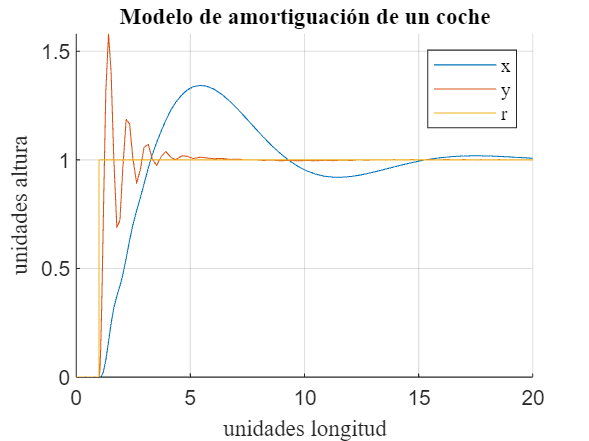

[m, n] = size(x);

for i =1:n
    figure
    hold on
    plot(signal_time, x(:,i))
    hold on
    plot(signal_time, y(:,i))
    grid on
    plot(signal_time, r_terreno(:,i))
    grid on
    xlabel("unidades longitud","FontName","latex");
    ylabel("unidades altura","FontName","latex");
    title(['Modelo de amortiguación de un coche'],'FontName','latex');
    legend('x','y','r','FontName','latex');
    hold off
end 

Observamos que el movimiento del coche está amortiguado, la curva *x *traza un movimiento más uniforme que la de *y*, ya que el resorte avanza por el terreno y el muelle amortigua al coche.

### ***Funciones disponibles para todas las secciones***

MATLAB permite utilizar la última sección de un livescript para definir funciones globales.

**Decorador de la función sim de MATLAB**

Esta función ejecuta la función sim, tras establecer los parámetros del solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

function sim_data = sim_config(model_name, solver)

Carga del modelo con load_system

load_system(model_name)
% open_system(model_name) will also open it

Configuración con set_param

% Set solver parameters
set_param(model_name, ...
    SolverType  = solver.type, ...
    SolverName  = solver.name, ...
    StartTime   = string(solver.start),...
    StopTime    = string(solver.stop), ...
    FixedStep   = string(solver.step) ...
    )
% More model parameters can be retrieved with:
% model_data = get_param(model_name, "ObjectParameters")
% Access blocks params with "model_name/block_name"

Simulación del modelo con sim

sim_data = sim(model_name);
% SimulationMode="normal" by default
end

Se utiliza el bloque Out1 para cada señal.